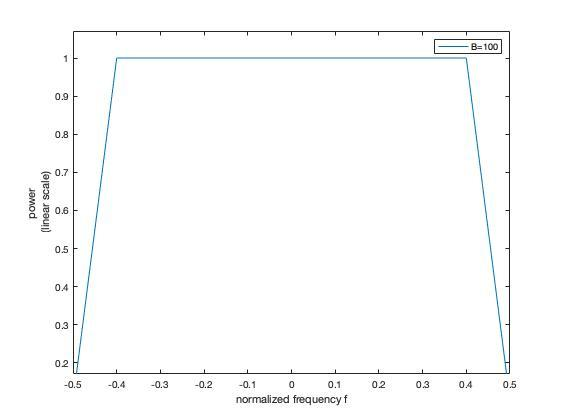

Concave SEM using [Disciplined Convex Programming](https://dcp.stanford.edu/)

function SEM = dcp_SEM(delta_f, f_range, R)
    % Generate only the positive part
    f = f_range(1):delta_f:f_range(2);
    
    % SEM = min(0, -((40/(60-19))*B*f) + (-40+60*(40/(60-19))) ); % dB
%     try
        SEM = min(1, (-R*100*3.332*(f-0.5))); % linear
%     catch ME
%         SEM = min(1, (-Ts*100*3.332*(f-0.5))); % linear
%     end
    % Generate the negative part
    SEM = [fliplr(SEM(2:end)) SEM]';
end